## Read Data from Remote Target

%remotecopy -local . -from -remote ~/Wetterlog/Wetterlog.csv

## Import Data from CSV

opts = delimitedTextImportOptions("NumVariables", 11);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["Year", "Month", "Day", "Hour", "Minute", "Second", "RelativeHumidity", "Temperature", "AtmosphericPressure","UP", "bmp_temperature", "Lightintensity"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
%Wetterlog = readtable(".\Wetterlog.csv", opts)
%clear opts

## Read all *.csv files in directory

clear Wetterlog
ds = tabularTextDatastore(".",'FileExtensions','.csv');
for i = 1:length(ds.Files)
    csvData = readtable(string(ds.Files(i)),opts);
    disp(string(ds.Files(i)))
    if isnan(csvData.Year(1))
        csvData(1,:) = [];
    end
    if i == 1
        Wetterlog = csvData;
    else
        Wetterlog = [Wetterlog; csvData];
    end
end

E:\Users\Andreas\Andreas\Private Elektronik\Wetterstation\Wetterlog.csv
E:\Users\Andreas\Andreas\Private Elektronik\Wetterstation\Wetterlog2020-10-05.csv
E:\Users\Andreas\Andreas\Private Elektronik\Wetterstation\Wetterlog2020-10-06.csv
E:\Users\Andreas\Andreas\Private Elektronik\Wetterstation\Wetterlog2020-10-07.csv
E:\Users\Andreas\Andreas\Private Elektronik\Wetterstation\Wetterlog2020-10-08.csv
E:\Users\Andreas\Andreas\Private Elektronik\Wetterstation\Wetterlog2020-10-09.csv
E:\Users\Andreas\Andreas\Private Elektronik\Wetterstation\Wetterlog2020-10-10.csv
E:\Users\Andreas\Andreas\Private Elektronik\Wetterstation\Wetterlog2020-10-11.csv
E:\Users\Andreas\Andreas\Private Elektronik\Wetterstation\Wetterlog2020-10-12.csv
E:\Users\Andreas\Andreas\Private Elektronik\Wetterstation\Wetterlog2020-10-13.csv
E:\Users\Andreas\Andreas\Private Elektronik\Wetterstation\Wetterlog2020-10-14.csv
E:\Users\Andreas\Andreas\Private Elektronik\Wetterstation\Wetterlog2020-10-15.csv
E:\Users\Andreas\Andreas\P

clear opts csvData i

## Convert Date-String to Date-Type in Matlab

if isnan(Wetterlog.Year(1))
    disp("nan detected")
    Wetterlog(1,:) = [];
end
%Wetterlog;

Datum = NaT(size(Wetterlog,1),1);
Datum(:,:) = datetime(Wetterlog.Year,...
        Wetterlog.Month,...
        Wetterlog.Day,...
        Wetterlog.Hour+1,...
        Wetterlog.Minute,...
        Wetterlog.Second);
disp("Last measurement at " + datestr(Datum(end)))

Last measurement at 24-Oct-2020 13:56:06


## Plot Data from Sensors

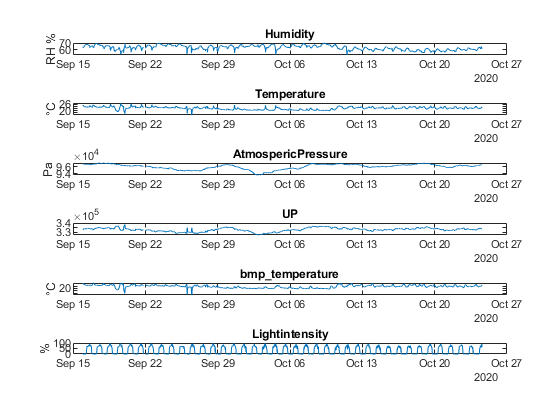

delete_entries = find(Wetterlog.AtmosphericPressure>120000);
delete_entries = [delete_entries,find(Wetterlog.RelativeHumidity<10)];
Wetterlog(delete_entries,:) = [];
Datum(delete_entries) = [];
Wetterlog.Lightintensity = Wetterlog.Lightintensity*100/409.6;

figure
sub1 = subplot(6,1,1);
plot(Datum,Wetterlog.RelativeHumidity)
title("Humidity")
ylabel("RH %")
sub2 = subplot(6,1,2);
plot(Datum,Wetterlog.Temperature)
title("Temperature")
ylabel("°C")
sub3 = subplot(6,1,3);
plot(Datum,Wetterlog.AtmosphericPressure)
title("AtmospericPressure")
ylabel("Pa")
sub4 = subplot(6,1,4);
plot(Datum,Wetterlog.UP)
title("UP")
sub5 = subplot(6,1,5);
plot(Datum,Wetterlog.bmp_temperature)
title("bmp\_temperature")
ylabel("°C")
sub6 = subplot(6,1,6);
plot(Datum,Wetterlog.Lightintensity)
title("Lightintensity")
ylabel("%")

linkaxes([sub1,sub2,sub3,sub4,sub5,sub6],"x");

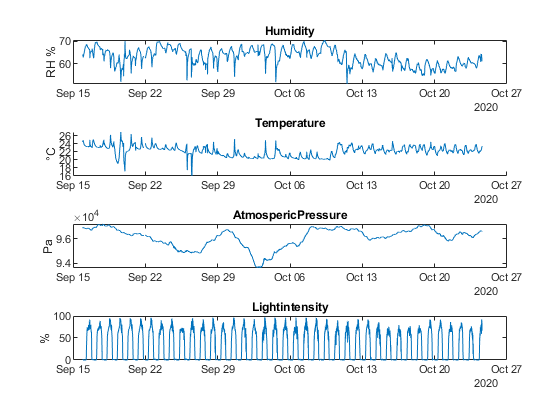

figure
sub1 = subplot(4,1,1);
plot(Datum,Wetterlog.RelativeHumidity)
title("Humidity")
ylabel("RH %")
sub2 = subplot(4,1,2);
hold on
plot(Datum,Wetterlog.Temperature)
% [TemperaturMittel,std] = Mittelwertfilter((Wetterlog.Temperature.'),3600*12);
% plot(Datum,TemperaturMittel.')
hold off
title("Temperature")
ylabel("°C")
sub3 = subplot(4,1,3);
plot(Datum,Wetterlog.AtmosphericPressure)
title("AtmospericPressure")
ylabel("Pa")
sub4 = subplot(4,1,4);
plot(Datum,Wetterlog.Lightintensity)
title("Lightintensity")
ylabel("%")

linkaxes([sub1,sub2,sub3,sub4],"x");

test.UT = 27898;
test.UP = 23843;
test.oss = 0;
[T,P] = calc_pressure(test.UT,test.UP,test.oss);

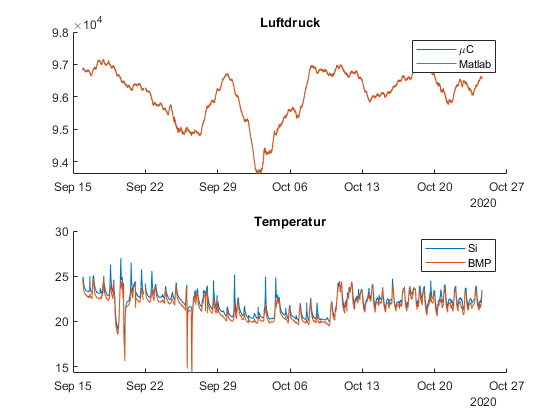

[T,P] = calc_pressure(Wetterlog.bmp_temperature,Wetterlog.UP,3);
[P] = calc_pressure_T_UP(Wetterlog.bmp_temperature,Wetterlog.UP,3);
T = Wetterlog.bmp_temperature;

%[P,~] = Mittelwertfilter(P.',floor(length(P)/16));
P = P.';

figure
sub1 = subplot(2,1,1);
hold on
plot(Datum,Wetterlog.AtmosphericPressure)
plot(Datum,P)
hold off
legend("\muC","Matlab")
title("Luftdruck")
sub2 = subplot(2,1,2);
hold on
plot(Datum,Wetterlog.Temperature)
plot(Datum,T)
hold off
title("Temperatur")
legend("Si","BMP")

linkaxes([sub1,sub2],"x");

## Calculate means

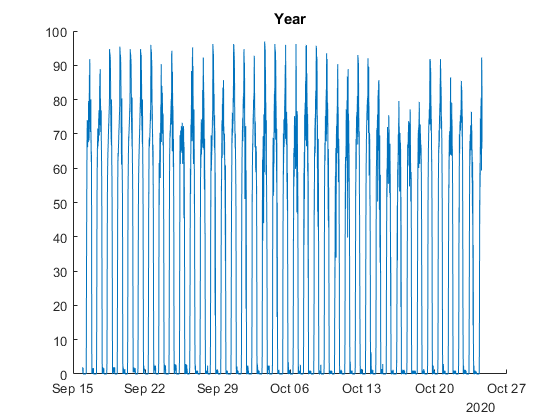

clear values values_mean

values = {};
value_pos = [7,8,9,12];

figure
hold on
for i = min(year(Datum)):max(year(Datum))
    year_pos{i} = find(year(Datum)==i);
    for j = 1:4
        values.Year{i,j} = Wetterlog(year_pos{i},value_pos(j));
        values_mean.Year(i,j) = mean(values.Year{i,j}.Variables);
    end
    plot(Datum(year_pos{i}),Wetterlog.Lightintensity(year_pos{i}))
end
hold off
title("Year")

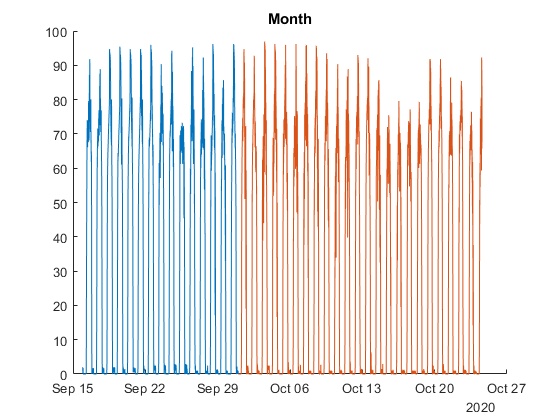


figure
hold on
for i = 1:12
    month_pos{i} = find(month(Datum)==i);
    for j = 1:4
        values.Month{i,j} = Wetterlog(month_pos{i},value_pos(j));
        values_mean.Month(i,j) = mean(values.Month{i,j}.Variables);
    end
    plot(Datum(month_pos{i}),Wetterlog.Lightintensity(month_pos{i}))
end
hold off
title("Month")

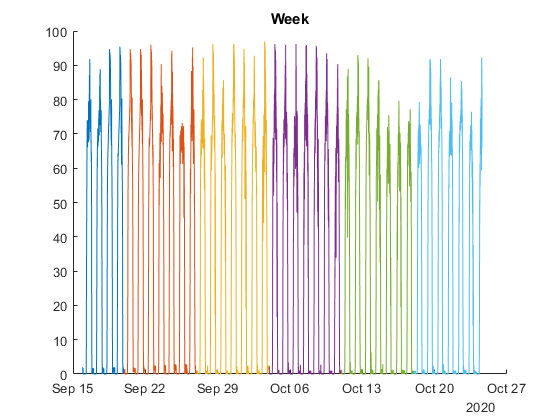


figure
hold on
for i = 1:52
    week_pos{i} = find(week(Datum)==i);
    for j = 1:4
        values.Week{i,j} = Wetterlog(week_pos{i},value_pos(j));
        values_mean.Week(i,j) = mean(values.Week{i,j}.Variables);
    end
    plot(Datum(week_pos{i}),Wetterlog.Lightintensity(week_pos{i}))
end
hold off
title("Week")

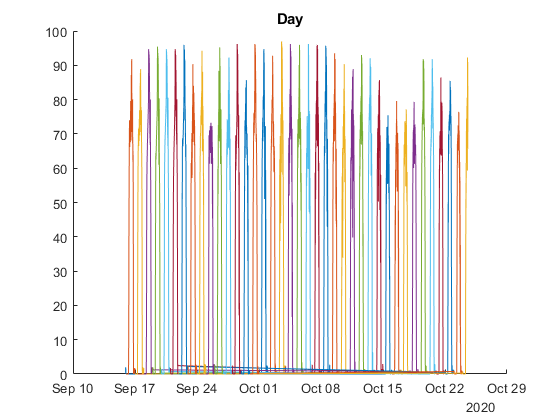


figure
hold on
for i = 1:31
    day_pos{i} = find(day(Datum)==i);
    for j = 1:4
        values.Day{i,j} = Wetterlog(day_pos{i},value_pos(j));
        values_mean.Day(i,j) = mean(values.Day{i,j}.Variables);
    end
    plot(Datum(day_pos{i}),Wetterlog.Lightintensity(day_pos{i}))
end
hold off
title("Day")

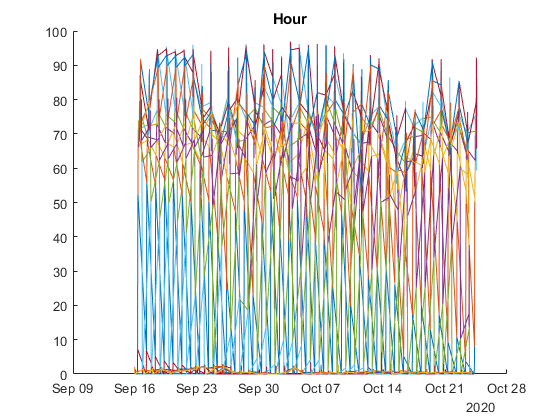


figure
hold on
for i = 1:24
    hour_pos{i} = find(hour(Datum)==i-1);
    for j = 1:4
        values.Hour{i,j} = Wetterlog(hour_pos{i},value_pos(j));
        values_mean.Hour(i,j) = mean(values.Hour{i,j}.Variables);
    end
    plot(Datum(hour_pos{i}),Wetterlog.Lightintensity(hour_pos{i}))
end
hold off
legend_array = ["0h","1h","2h","3h","4h","5h","6h","7h","8h","9h","10h","11h","12h",...
    "13h","14h","15h","16h","17h","18h","19h","20h","21h","22hh","23h"];
%legend(legend_array)
title("Hour")

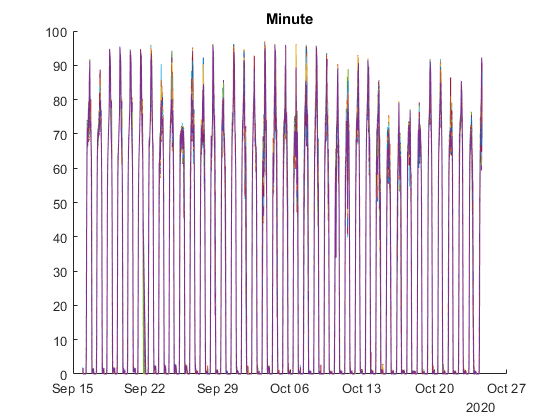



figure
hold on
for i = 1:60
    minute_pos{i} = find(minute(Datum)==i-1);
    for j = 1:4
        values.Minute{i,j} = Wetterlog(minute_pos{i},value_pos(j));
        values_mean.Minute(i,j) = mean(values.Minute{i,j}.Variables);
    end
    plot(Datum(minute_pos{i}),Wetterlog.Lightintensity(minute_pos{i}))
end
hold off
title("Minute")

## Plot means

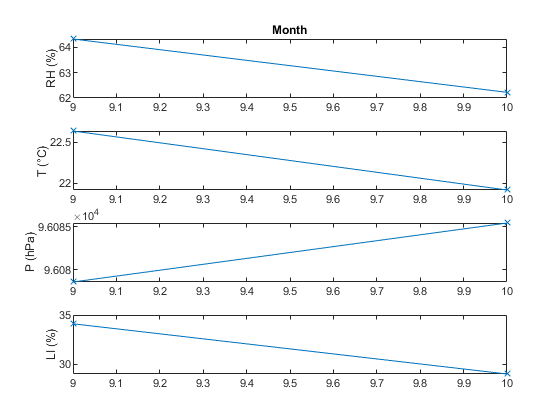

x_labels = ["RH (%)","T (°C)","P (hPa)","LI (%)"];

figure
for i = 1:4
    subplot(4,1,i)
    plot(values_mean.Month(:,i),"-x")
    ylabel(x_labels(i))
    if i == 1
        title("Month")
    end
end

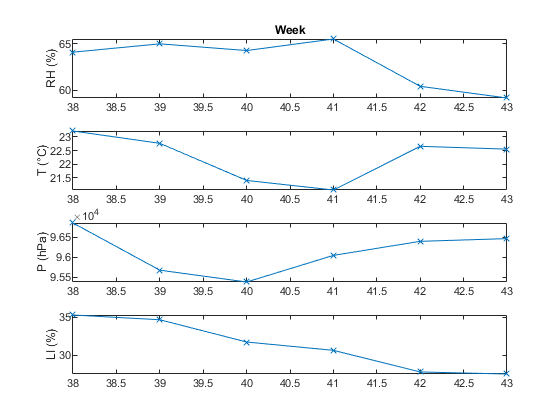


figure
for i = 1:4
    subplot(4,1,i)
    plot(values_mean.Week(:,i),"-x")
    ylabel(x_labels(i))
    if i == 1
        title("Week")
    end
end

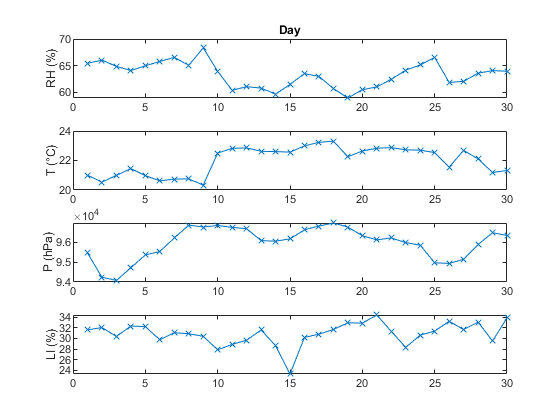


figure
for i = 1:4
    subplot(4,1,i)
    plot(values_mean.Day(:,i),"-x")
    ylabel(x_labels(i))
    if i == 1
        title("Day")
    end
end

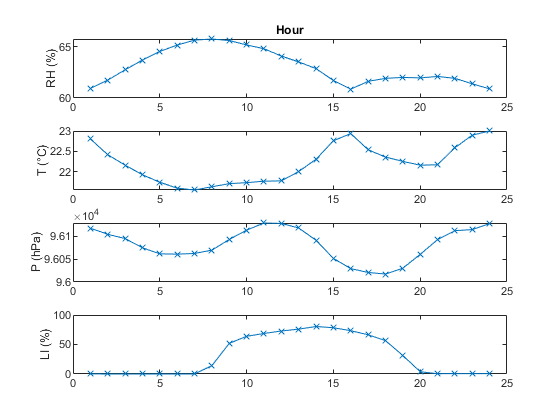


figure
for i = 1:4
    subplot(4,1,i)
    plot(values_mean.Hour(:,i),"-x")
    ylabel(x_labels(i))
    if i == 1
        title("Hour")
    end
end

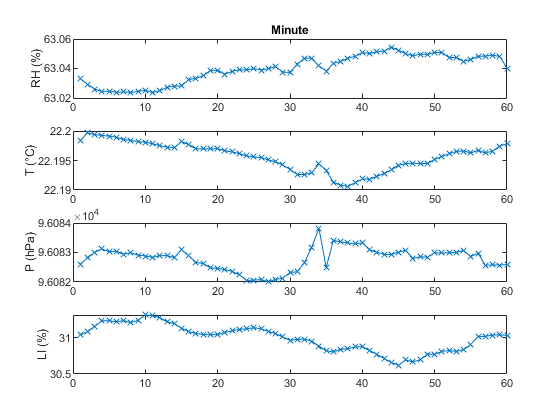


figure
for i = 1:4
    subplot(4,1,i)
    plot(values_mean.Minute(:,i),"-x")
    ylabel(x_labels(i))
    if i == 1
        title("Minute")
    end
end